IJ = Fiji('E:\work\SPR-DF\Ag-FeCl3\20230327_ZKLM_80nmAgNP_40mW_concentration\A2_100fps_1mM', ...
    700, 3700);

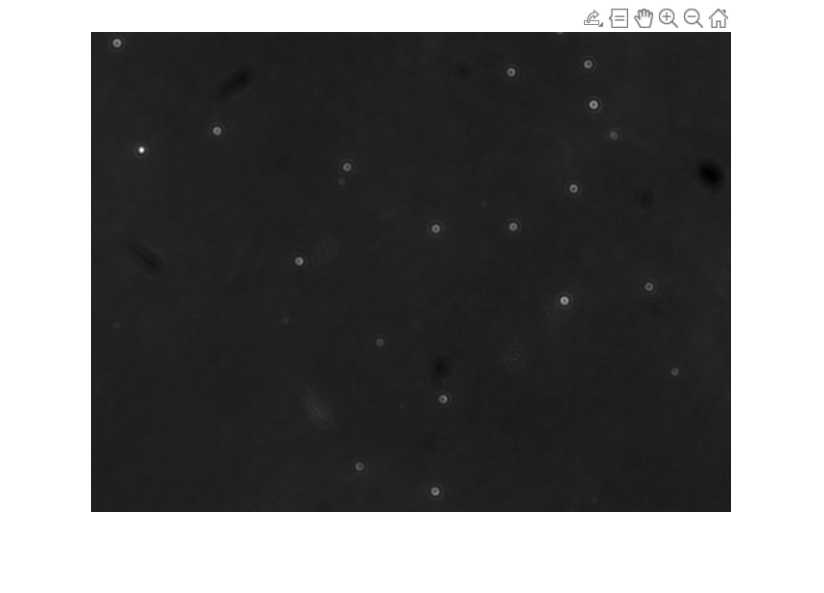

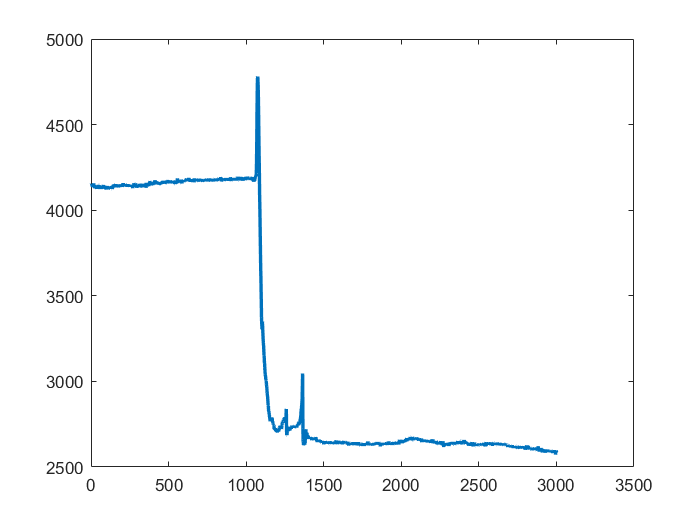

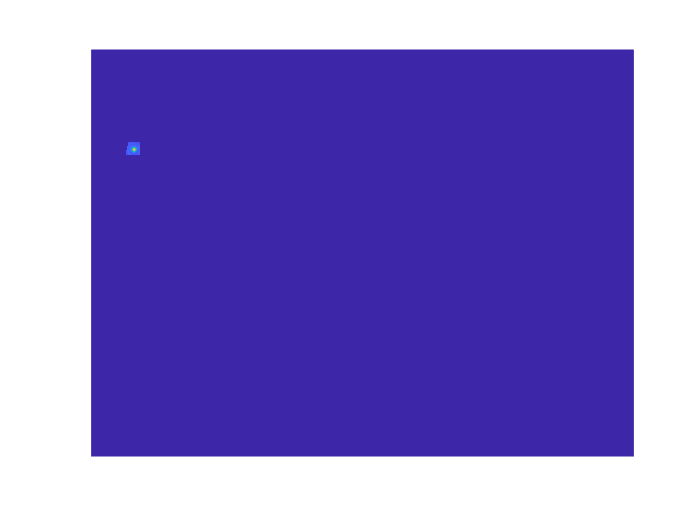

close all

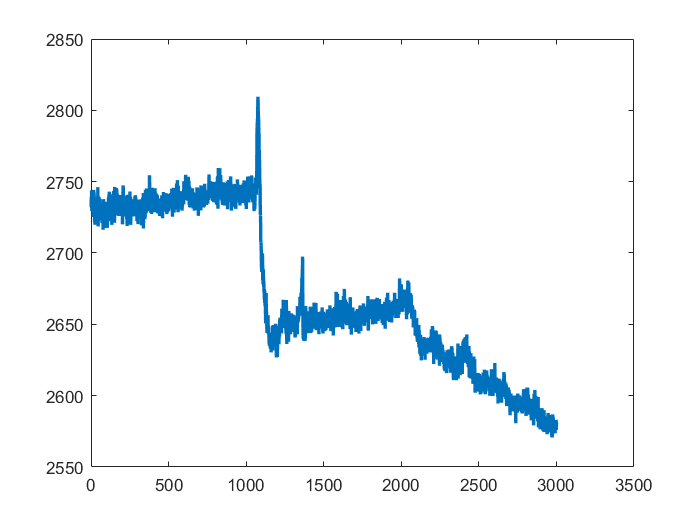

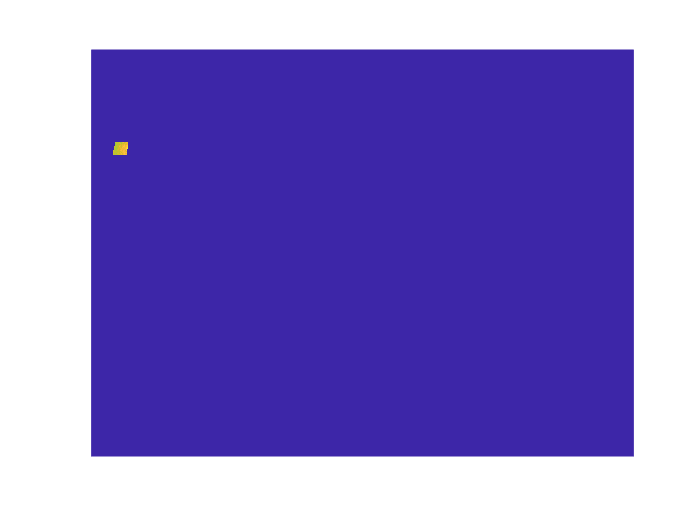

[I1, ROI1] = IJ.Q('ROI', 0);
ROI2 = IJ.m_trans(ROI1, -0, -15);
[I2, ~] = IJ.Q('ROI', ROI2);

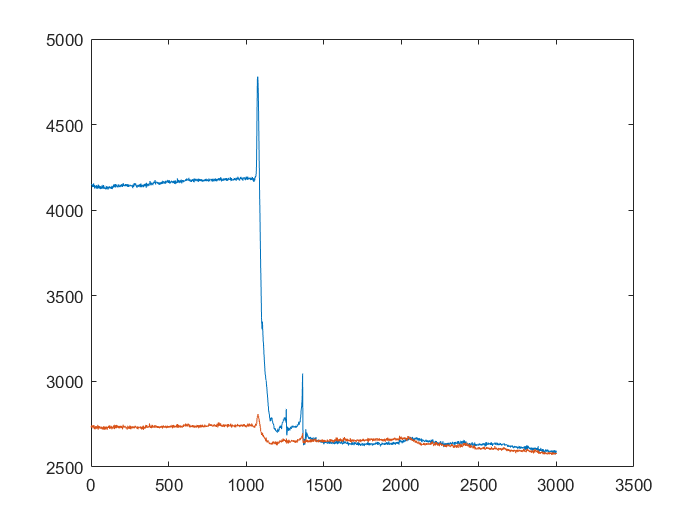

figure
plot(I1); hold on; plot(I2);

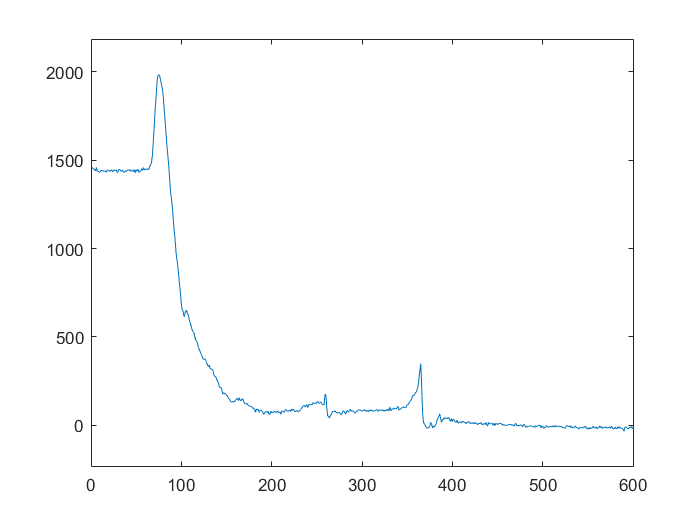

figure
ind = 1:800;
temp1 = I1(ind) - I2(ind); temp2 = 0.1*(max(temp1)-min(temp1));
plot(temp1)
xlim([0, length(ind)]);
ylim([min(temp1) - temp2, max(temp1) + temp2])

figure
plot(temp1)
[~, ~, ~, p] = findpeaks(temp1);
proms = 5*median(p);
[pks, locs] = findpeaks(temp1, 'MinPeakProminence', proms);
text(locs+.02,pks,num2str((1:numel(pks))'))

temp3 = -temp1;
hold on
plot(temp3)
[~, ~, ~, p] = findpeaks(temp3);
proms = 5*median(p);
[pks, locs] = findpeaks(temp3, 'MinPeakProminence', proms);
text(locs+.02,pks,num2str((1:numel(pks))'))

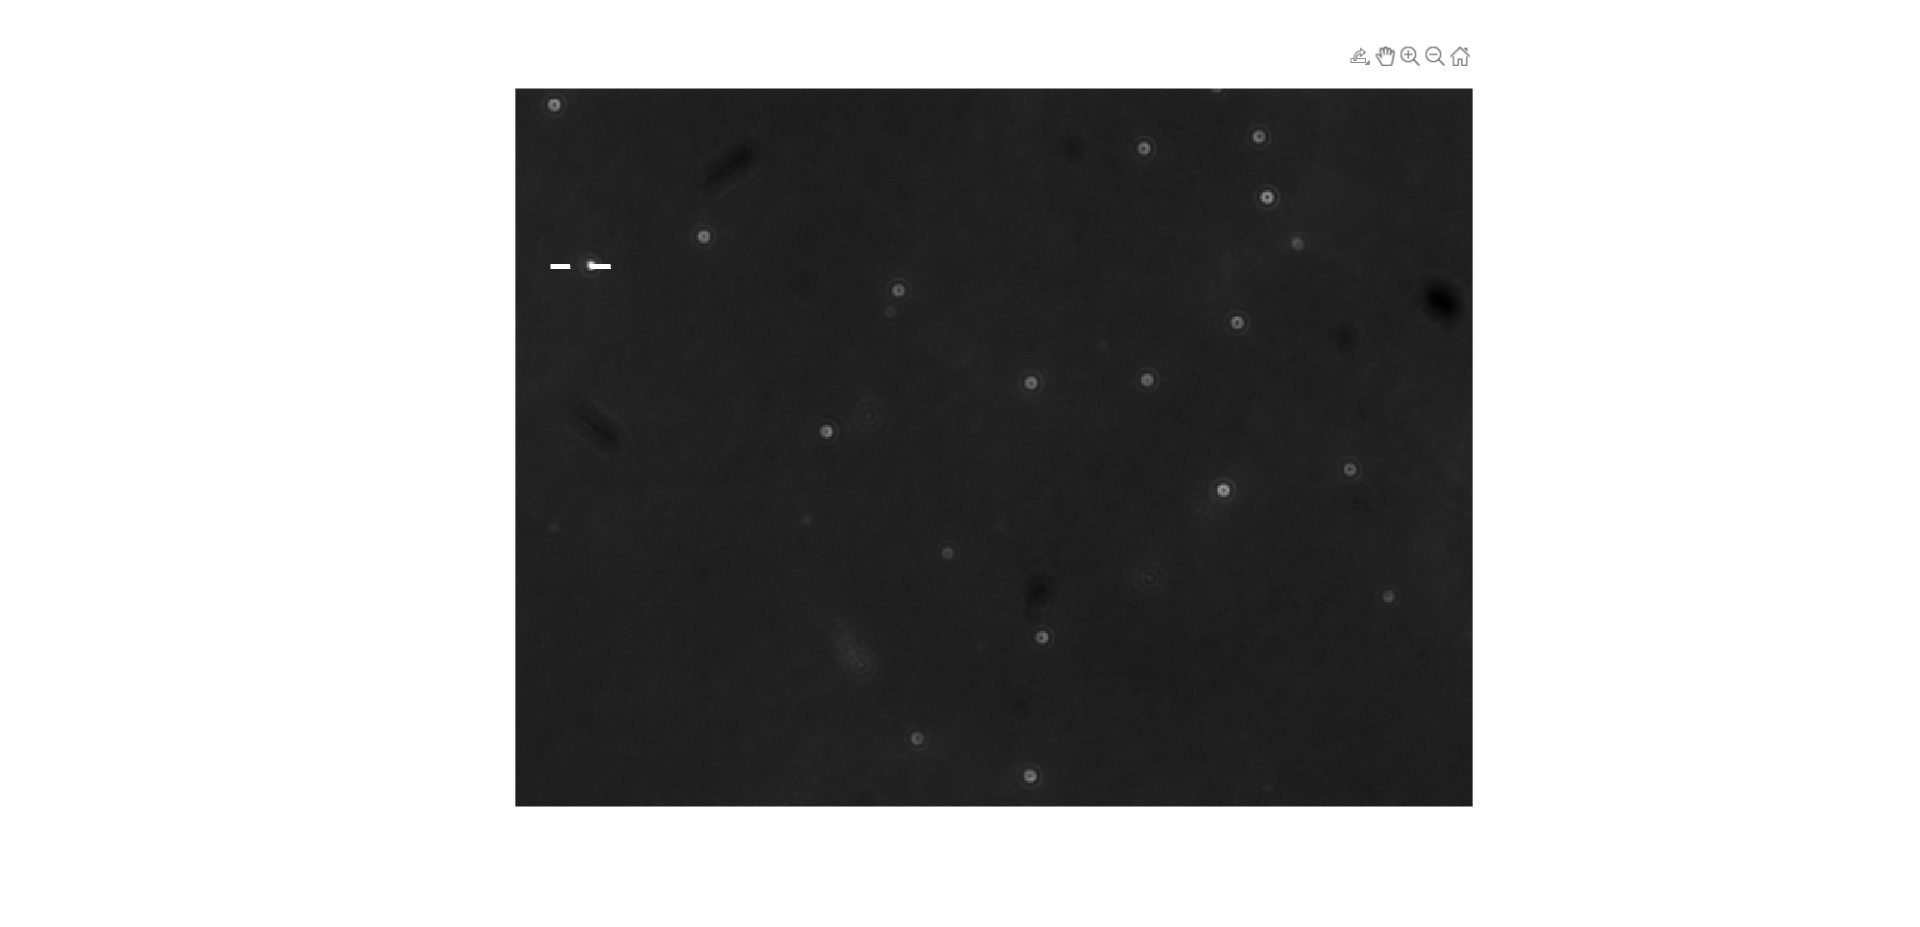

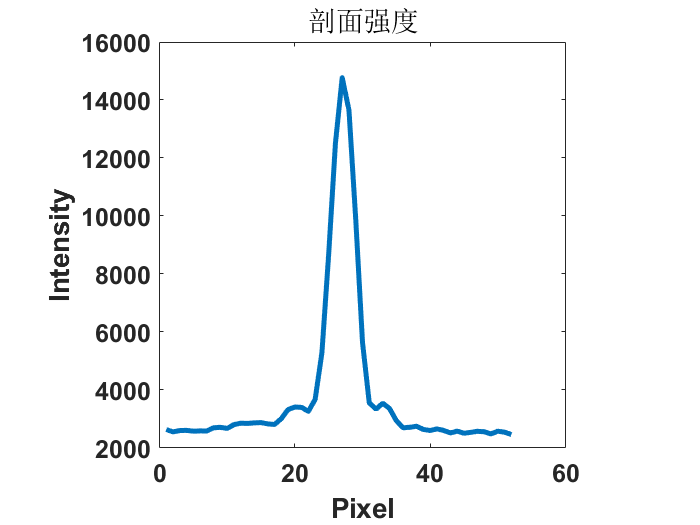

intensity1 = IJ.LineCut();

intensity2= IJ.LineCut();
intensity3= IJ.LineCut('frame', 1356);
intensity3 = intensity3(39-20:39+20);

intensity1 = (intensity1-min(intensity1))/(max(intensity1)-min(intensity1));
intensity2 = (intensity2-min(intensity2))/(max(intensity2)-min(intensity2));
intensity3 = (intensity3-min(intensity3))/(max(intensity3)-min(intensity3));

figure
plot(intensity3(21-20:21+20));
hold on
plot(intensity2(47-20:47+20))